# Exercise 3

This is the code for exercise 3.

There was no instructions on what algorithm to use, so I am working under the assumption that using the bayesian updating method described in the previous steps is the correct way to move forward with this.

I'm assuming that the variance is 1, as that is consistent with the rest of the information given there.

## Part 1

The code and the implementation. It's just code, so not much to explain

% First is importing the data
data = readtable('periodic.csv');
data = table2array(data);

% Then we create the 3 theta values
theta_vals = normrnd(0, 100, 3, 1)

theta_vals =   140.9034
  141.7192
   67.1497



% Method to calculate the h values for a given t
calc_h_val = @(t) [1, t, sin(2*pi*t)]

calc_h_val = function_handle with value:
    @(t)[1,t,sin(2*pi*t)]



% Method to calculate the mk
calc_mk_val = @(pk, hk, yk, pk_prev_inv, mk_prev) pk*(hk.'*1*yk + pk_prev_inv*mk_prev)

calc_mk_val = function_handle with value:
    @(pk,hk,yk,pk_prev_inv,mk_prev)pk*(hk.'*1*yk+pk_prev_inv*mk_prev)


% Method to calculate the next pk value
calc_pk_val = @(pk_prev, hk) pk_prev - pk_prev*hk.'*(hk*pk_prev*hk.' + 1)^(-1)*hk*pk_prev

calc_pk_val = function_handle with value:
    @(pk_prev,hk)pk_prev-pk_prev*hk.'*(hk*pk_prev*hk.'+1)^(-1)*hk*pk_prev



% I will assume that P(0) is the identity times
% the theta values. Makes most sense given the information
start_pk = eye(3)

start_pk =      1     0     0
     0     1     0
     0     0     1



% And I will also that mk(0) is just the initial theta values

## Part 2

Given the dataset, finding the posterior mean and covariance matrix. First for 5 observations, then for all.

% Now that all of the parts have been boded, it is time to just put them
% together

cur_pk = start_pk;
cur_mk = theta_vals;

% First I will do this for the first 5 elements
target=5;
for i = 1:target
    % Doing the pk
    prev_pk = cur_pk;
    cur_pk = calc_pk_val(prev_pk, calc_h_val(data(i,1)));
    
    % Doing the mk values
    prev_mk = cur_mk;
    cur_mk = calc_mk_val(cur_pk, calc_h_val(data(i,1)), data(i, 2), inv(prev_pk), prev_mk);

end

prev_mk =   140.9034
  141.7192
   67.1497


prev_mk =    70.5542
  141.7192
   67.1497


prev_mk =    29.4807
  108.1899
   22.3357


prev_mk =    15.6481
   83.2896
   55.9187


prev_mk =    11.8771
   32.7862
   14.3707



% The mean is the mk, and the covariance is the pk
% We already have the current covariance, we just need to calculate the pk
pk_5 = cur_pk

pk_5 =     0.3118   -0.2139   -0.0202
   -0.2139    0.3156    0.0381
   -0.0202    0.0381    0.2783



mk_5 = cur_mk

mk_5 =    13.1191
   17.7207
   23.4193



cur_pk = start_pk;
cur_mk = theta_vals;

% Now for 
target=length(data);
for i = 1:target
    % Doing the pk
    prev_pk = cur_pk;
    cur_pk = calc_pk_val(prev_pk, calc_h_val(data(i,1)));
    
    % Doing the mk values
    prev_mk = cur_mk;
    cur_mk = calc_mk_val(cur_pk, calc_h_val(data(i,1)), data(i, 2), inv(prev_pk), prev_mk);

end

% The mean is the mk, and the covariance is the pk
% We already have the current covariance, we just need to calculate the pk
pk_all = cur_pk

pk_all =     0.0720   -0.0053   -0.0006
   -0.0053    0.0005    0.0001
   -0.0006    0.0001    0.0392



mk_all = cur_mk

mk_all =    10.5697
   -0.4973
    5.0357


The reason the values in the diagonal are smaller is because the original values come from a normal distribution with a high level of variance, so they are almost definitely too far from the truth.

By having more observations, there is more opportunity to hone in on the true value that needs to be learned.

## Part 3

Plot of curve and the data.

I transformed the data into a line plot for convenience.

% For we need to do a line plot with the function
%. This is pretty much just merging the mk values and the h function.
plot_for_5 = @(x) calc_h_val(x)*mk_5;
plot_for_all = @(x) calc_h_val(x)*mk_all;

hold on
a1 = fplot(plot_for_5); m1 = "5 elements";

a2 = fplot(plot_for_all); m2 = "All elements";

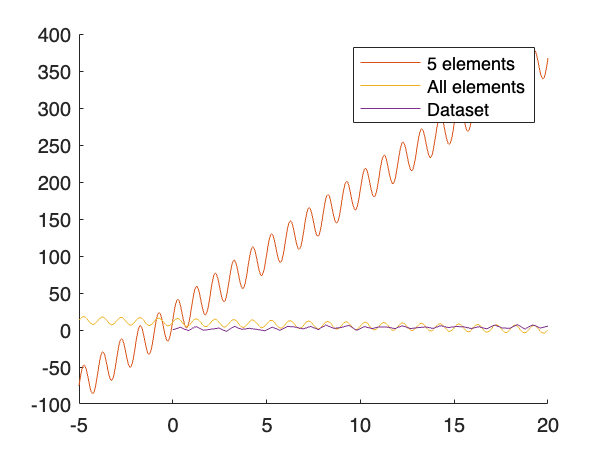

a3 = plot(data(:,1), data(:,2)); m3 = "Dataset";
legend([a1,a2,a3], [m1, m2, m3]);
hold off

clf

So, the plot for 5 was very wrong. Because of the size of it, it was hard to estimate how much I should see the rest of the plot. So I will redo this, but just plotting the classifier trained on the entire dataset, and the dataset.

hold on
a2 = fplot(plot_for_all); m2 = "All elements";

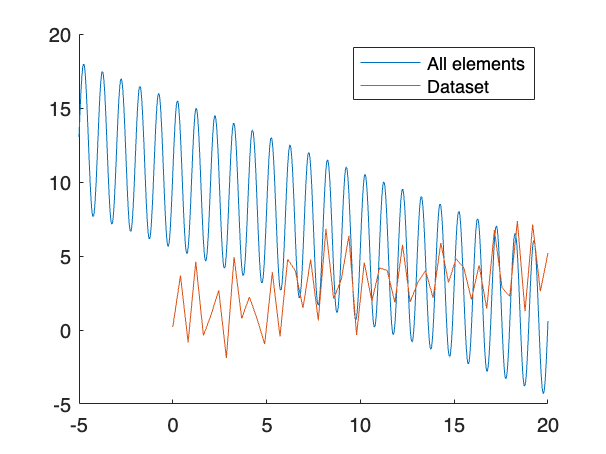

a3 = plot(data(:,1), data(:,2)); m3 = "Dataset";
legend([a2,a3], [m2, m3]);
hold off